# Communication Systems by J.G.Proakis

## Written by: Arman Miraghasi

### **Chapter 2 (Signals and Linear Systems)**

clc; clear; close all;

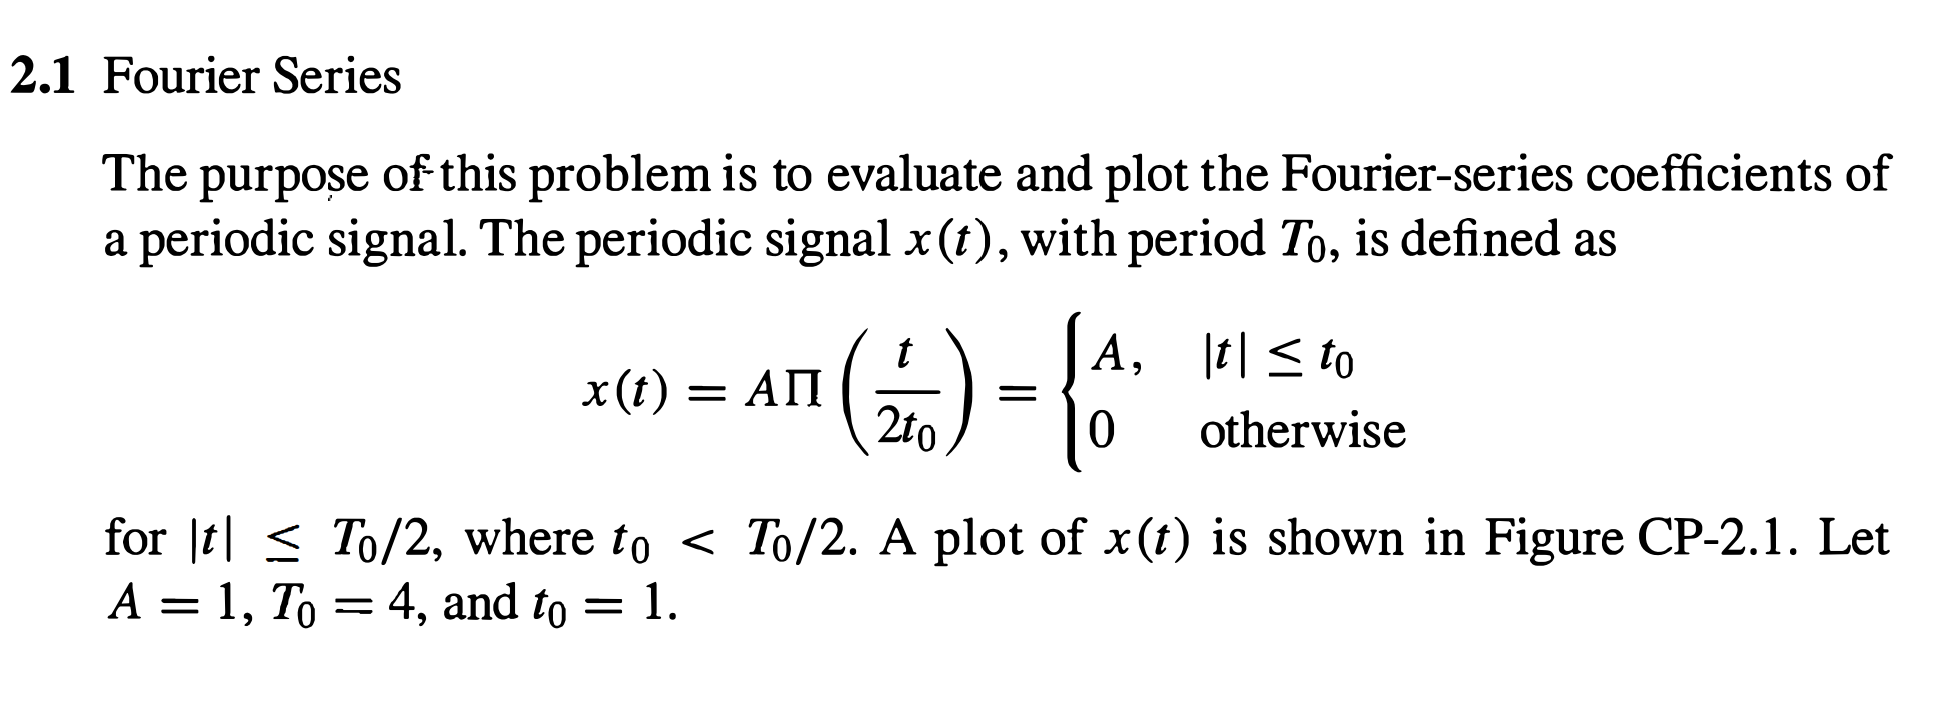

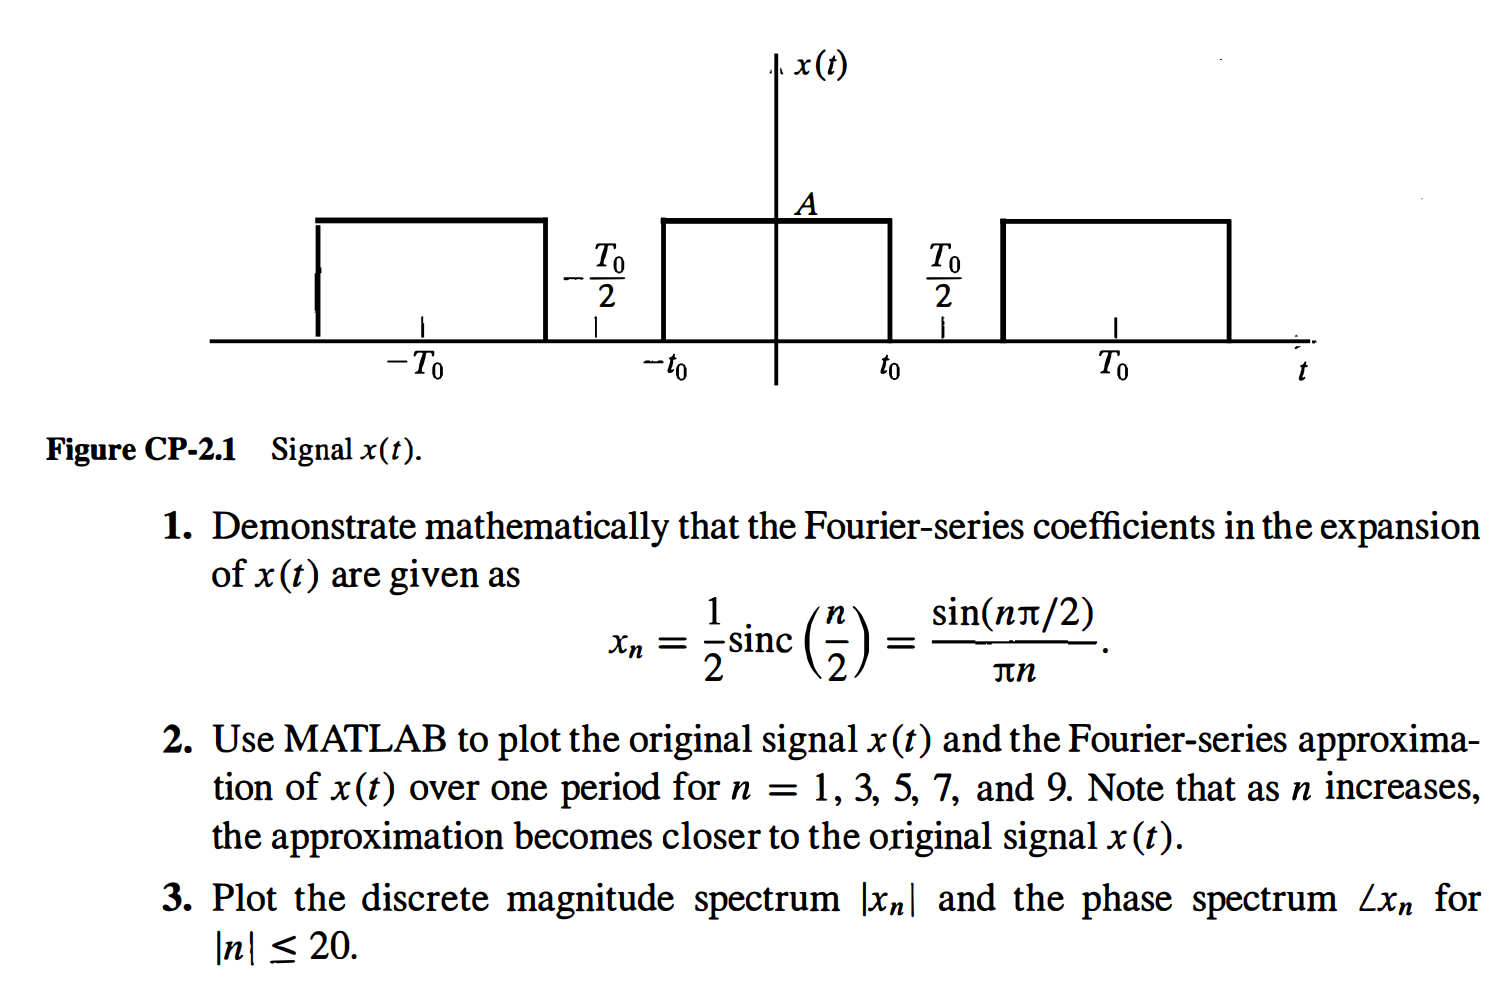

### Answer:

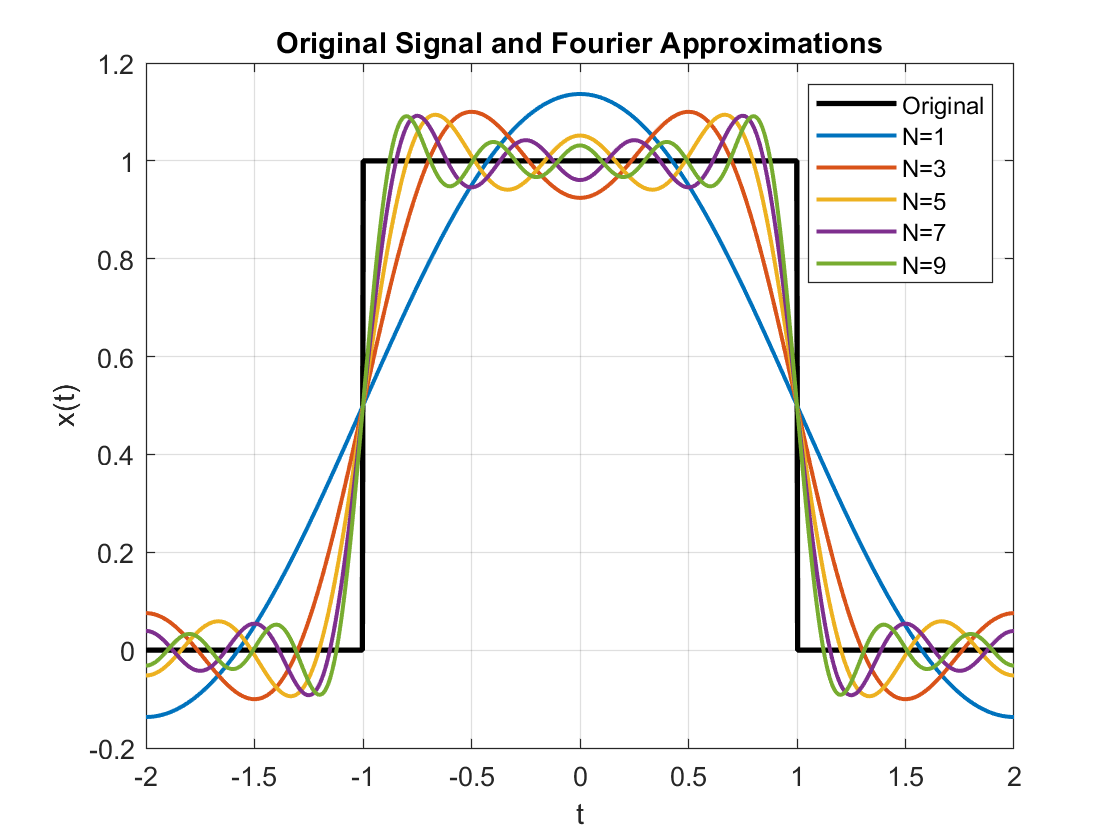

%% Parameters
A = 1; 
T0 = 4; 
t0 = 1;
w0 = 2*pi/T0;    % Fundamental frequency

%% Define original signal over one period
t = linspace(-T0/2, T0/2, 1000); 
x = zeros(size(t));
x(abs(t) <= t0) = A;   % rectangular pulse

%% Fourier coefficients function
x_n = @(n) (sin(n*pi/2)./(n*pi)); 
% handle n=0 separately (limit case)
x_0 = 0.5;  

%% Task 1: Plot original and Fourier approximations
figure;
plot(t, x, 'k', 'LineWidth', 2); hold on;

N_values = [1, 3, 5, 7, 9];  % different approximations
colors = lines(length(N_values));

for k = 1:length(N_values)
    N = N_values(k);
    x_approx = zeros(size(t));
    for n = -N:N
        if n == 0
            coeff = x_0;
        else
            coeff = x_n(n);
        end
        x_approx = x_approx + coeff * exp(1j*n*w0*t);
    end
    plot(t, real(x_approx), 'Color', colors(k,:), 'LineWidth', 1.5);
end

legend(['Original', arrayfun(@(N) sprintf('N=%d',N), N_values, 'UniformOutput', false)]);
xlabel('t'); ylabel('x(t)');
title('Original Signal and Fourier Approximations');
grid on;

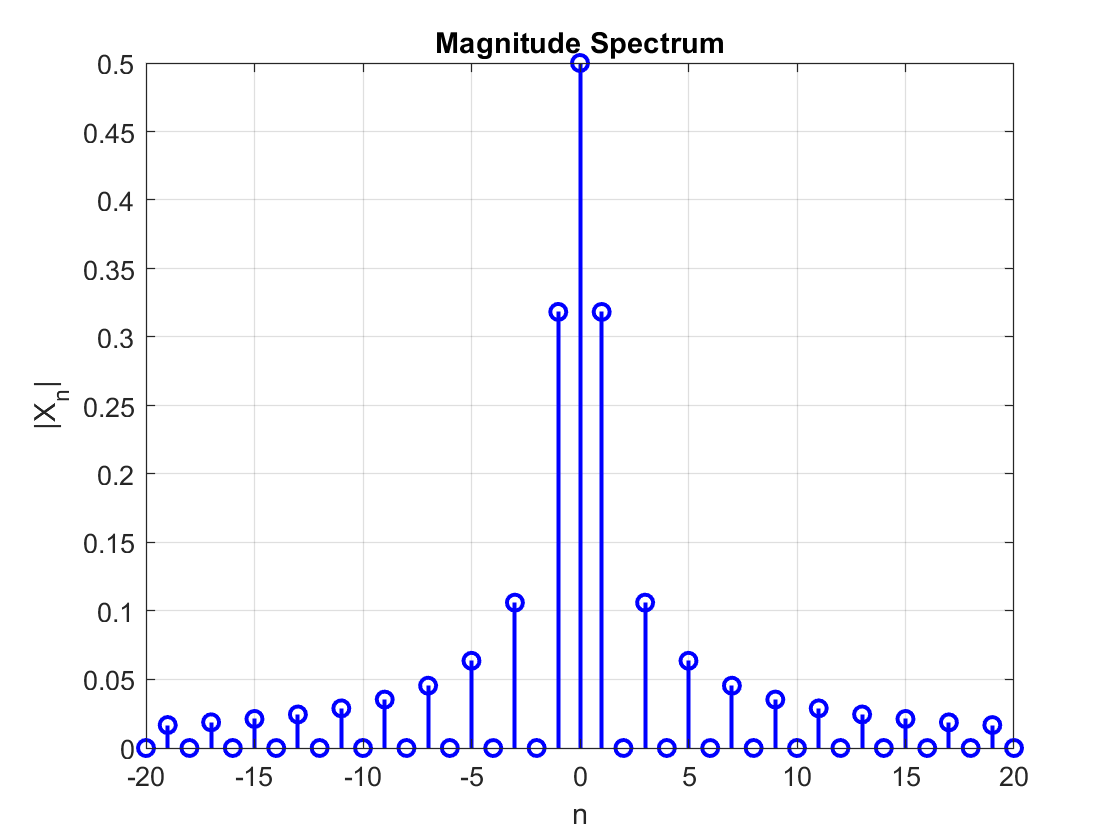

%% Task 2: Magnitude and Phase Spectrum for |n| <= 20
n_vals = -20:20;
Xn = zeros(size(n_vals));

for idx = 1:length(n_vals)
    n = n_vals(idx);
    if n == 0
        Xn(idx) = x_0;
    else
        Xn(idx) = x_n(n);
    end
end

% Magnitude Spectrum
figure;
stem(n_vals, abs(Xn), 'b','LineWidth',1.5);
xlabel('n'); ylabel('|X_n|');
title('Magnitude Spectrum');
grid on;

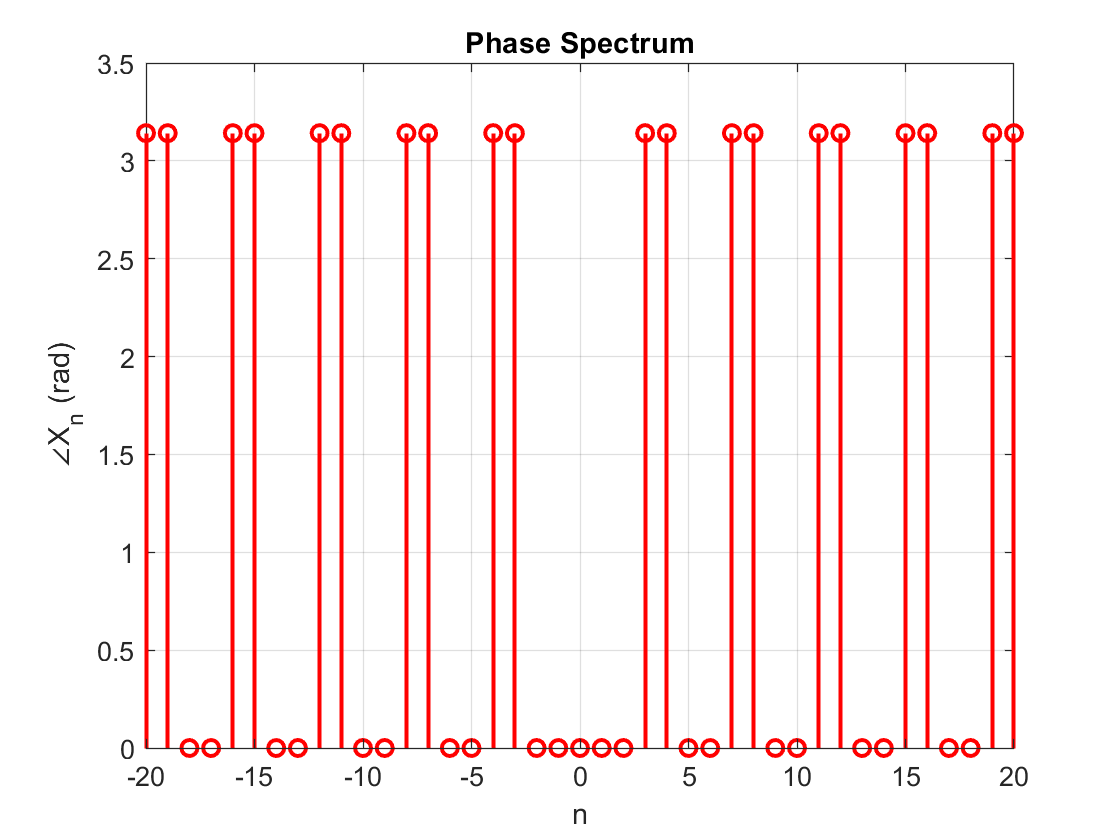

% Phase Spectrum
figure;
stem(n_vals, angle(Xn), 'r','LineWidth',1.5);
xlabel('n'); ylabel('∠X_n (rad)');
title('Phase Spectrum');
grid on;

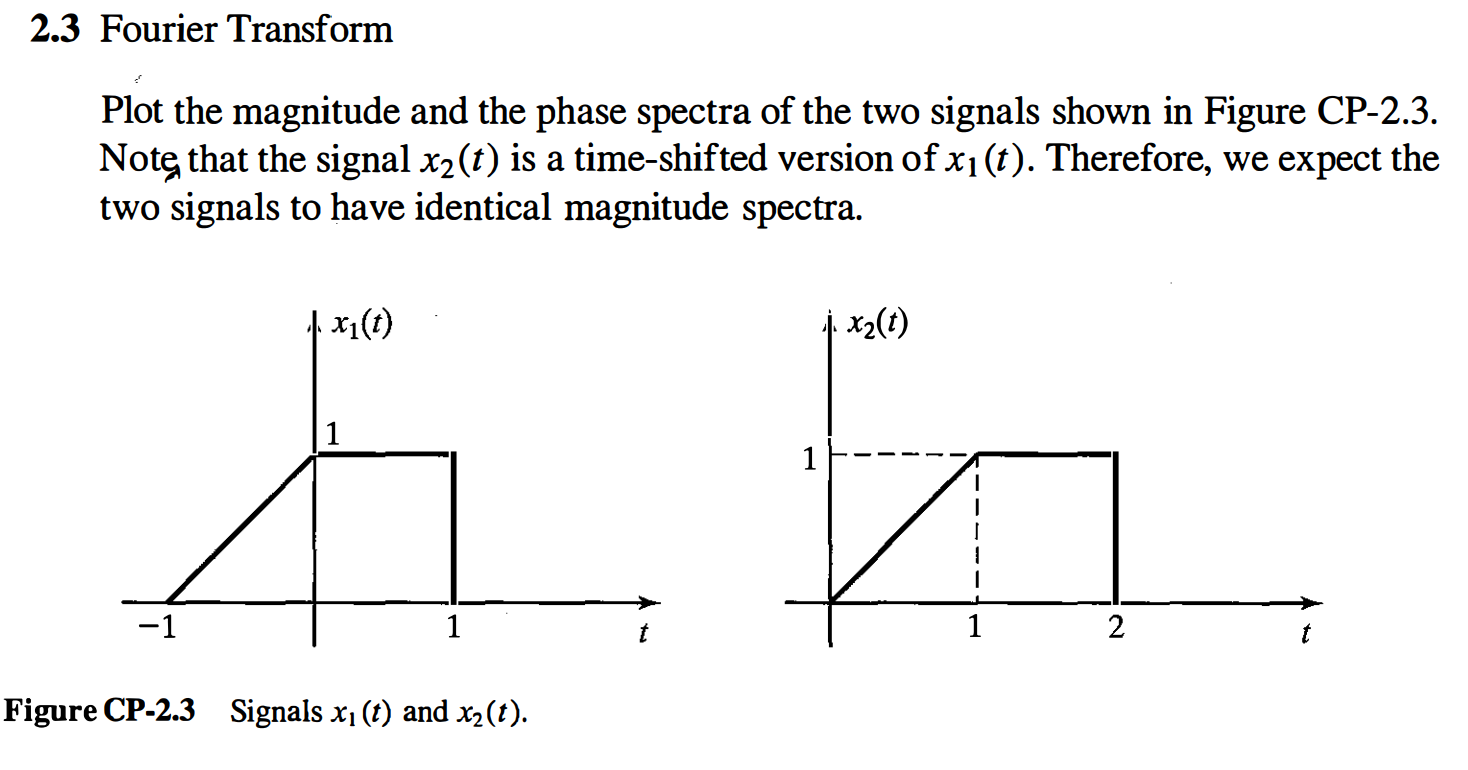

### Answer:

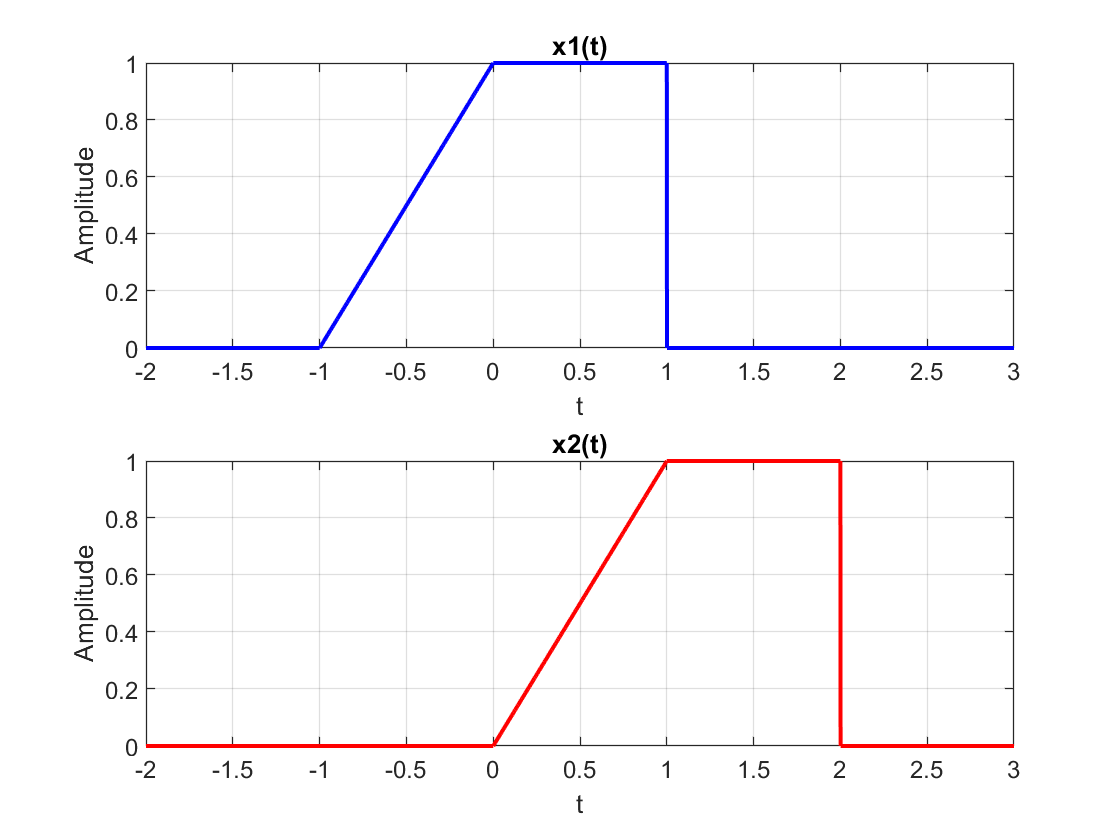

%% Time vector
Fs = 1000;              % sampling frequency
T = 1/Fs;               
t = -2:T:3;             % enough time window

%% Define signals
x1 = zeros(size(t));
x1((t >= -1) & (t < 0)) = t((t >= -1) & (t < 0)) + 1;  % ramp part
x1((t >= 0) & (t <= 1)) = 1;                           % constant part

x2 = zeros(size(t));
x2((t >= 0) & (t < 1)) = t((t >= 0) & (t < 1));        % ramp part
x2((t >= 1) & (t <= 2)) = 1;                           % constant part

%% Time domain signals for reference
figure;
subplot(2,1,1); plot(t,x1,'b','LineWidth',1.5); grid on;
title('x1(t)'); xlabel('t'); ylabel('Amplitude');
subplot(2,1,2); plot(t,x2,'r','LineWidth',1.5); grid on;
title('x2(t)'); xlabel('t'); ylabel('Amplitude');

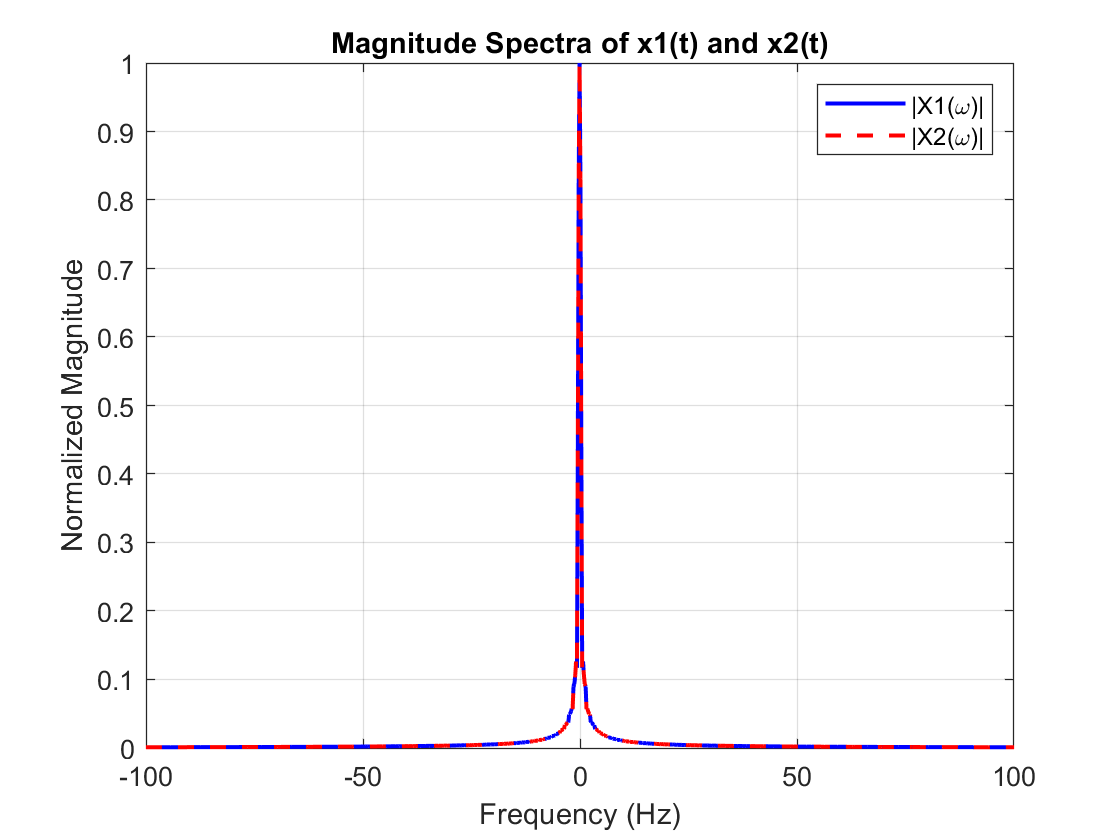

%% Fourier Transform using FFT
N = length(t);
f = (-N/2:N/2-1)*(Fs/N);     % frequency axis

X1 = fftshift(fft(x1, N));
X2 = fftshift(fft(x2, N));

%% Magnitude Spectra
figure;
plot(f, abs(X1)/max(abs(X1)), 'b', 'LineWidth',1.5); hold on;
plot(f, abs(X2)/max(abs(X2)), 'r--', 'LineWidth',1.5);
xlabel('Frequency (Hz)'); ylabel('Normalized Magnitude');
title('Magnitude Spectra of x1(t) and x2(t)');
xlim([-100 100]);
legend('|X1(\omega)|','|X2(\omega)|'); grid on;

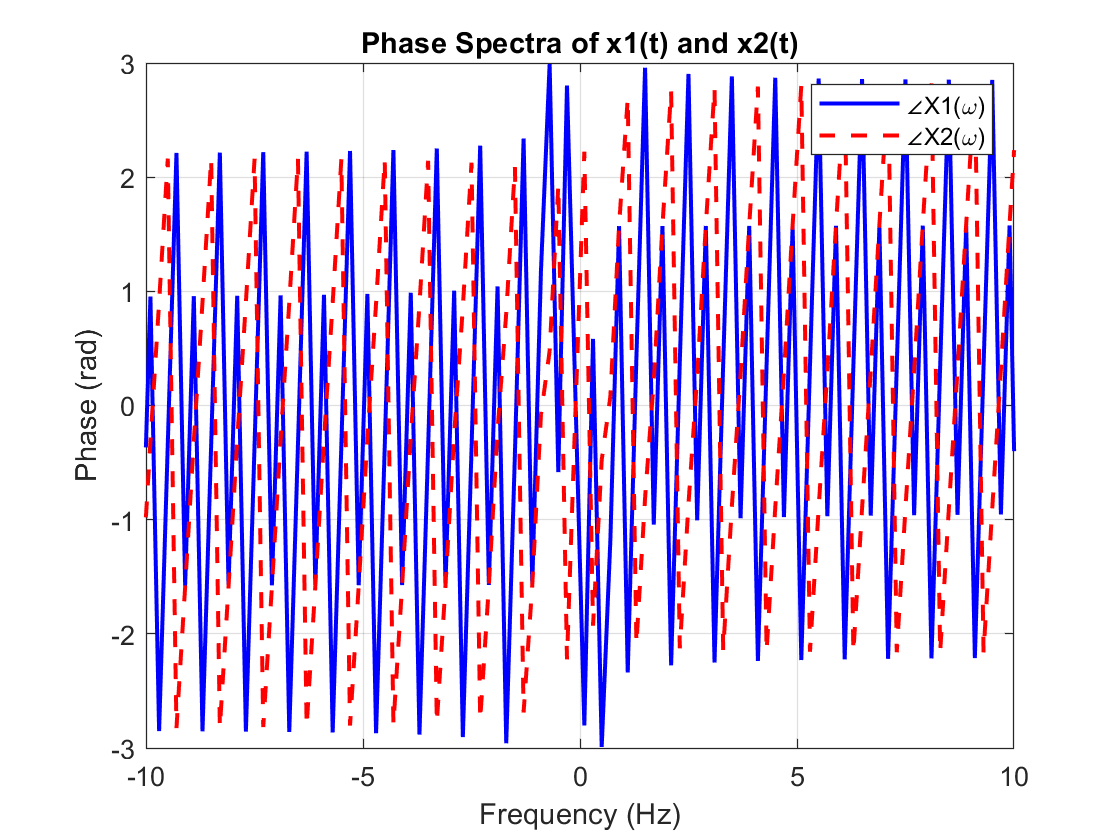

%% Phase Spectra
figure;
plot(f, angle(X1), 'b', 'LineWidth',1.5); hold on;
plot(f, angle(X2), 'r--', 'LineWidth',1.5);
xlabel('Frequency (Hz)'); ylabel('Phase (rad)');
title('Phase Spectra of x1(t) and x2(t)');
xlim([-10 10])
legend('∠X1(\omega)','∠X2(\omega)'); grid on;

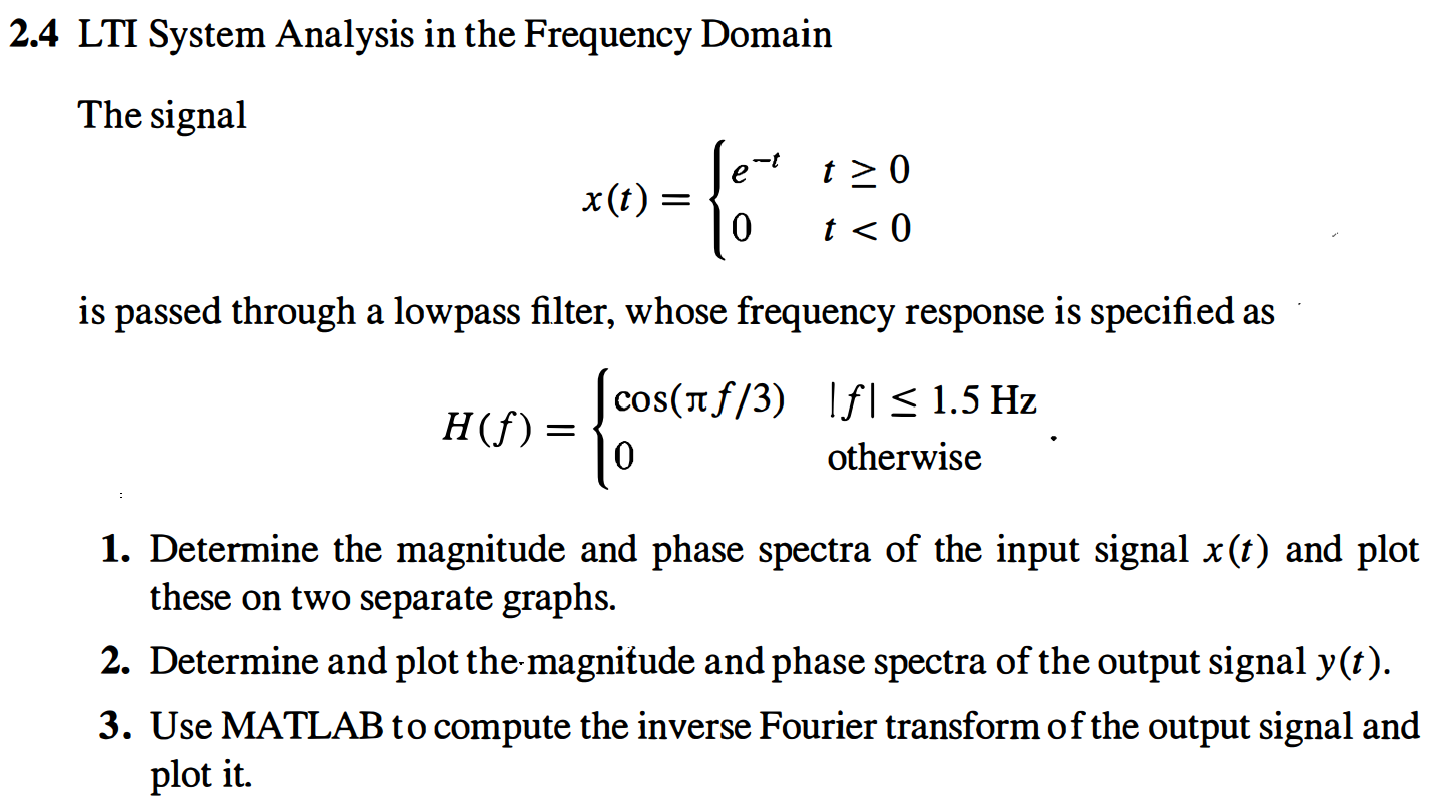

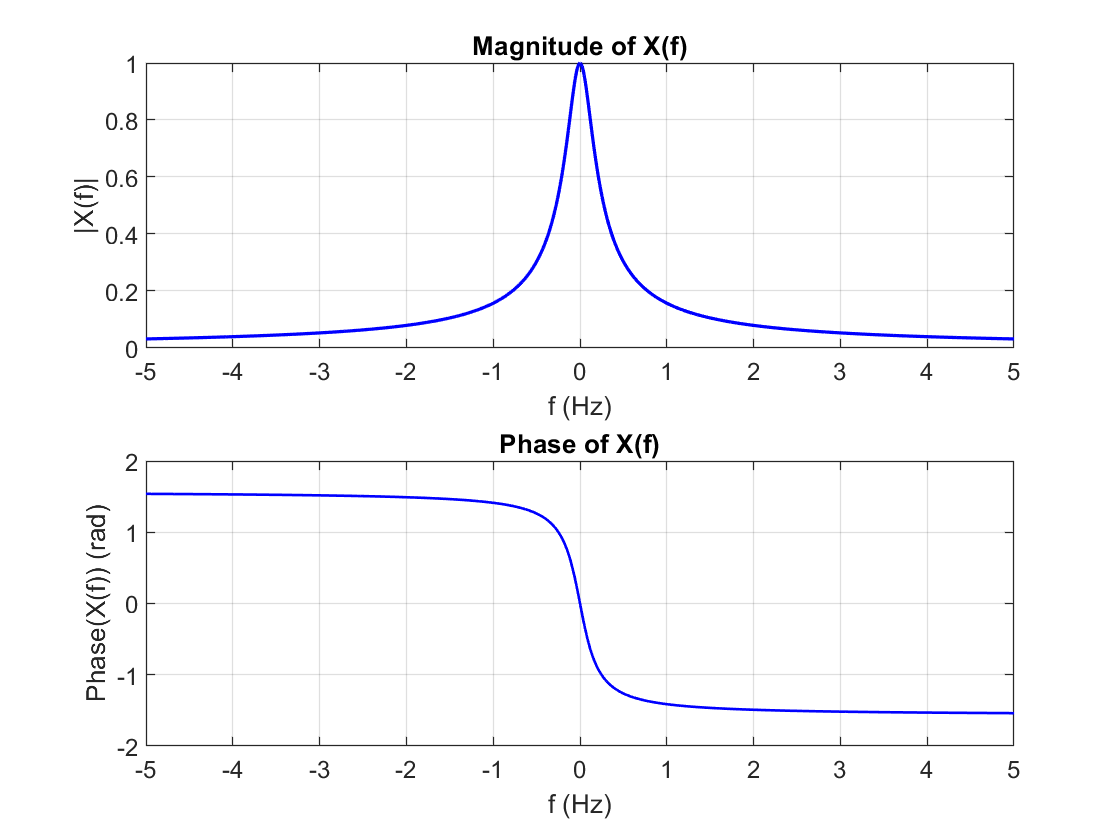

% parameters
Fmax = 50;        % max frequency (Hz) for plotting and numerical inversion
N = 8192;         % number of frequency samples (power of 2 recommended)
df = 2*Fmax / N;
f = -Fmax : df : (Fmax - df);   % frequency axis length N
if length(f)~=N, error('N mismatch'); end

% analytic X(f) = 1/(1 + j 2 pi f) 
Xf = 1 ./ (1 + 1j*2*pi.*f);

% magnitude & phase of input
magX = abs(Xf);
phX  = angle(Xf);    % principal value; -pi..pi

% Plots: input magnitude & phase
figure('Name','Input Spectrum','NumberTitle','off','Position',[100 100 560 420]);
subplot(2,1,1);
plot(f, magX, 'b','LineWidth',1.2);
xlim([-5 5]); xlabel('f (Hz)'); ylabel('|X(f)|'); grid on;
title('Magnitude of X(f)');

subplot(2,1,2);
plot(f, phX, 'b','LineWidth',1.0);
xlim([-5 5]); xlabel('f (Hz)'); ylabel('Phase(X(f)) (rad)'); grid on;
title('Phase of X(f)');

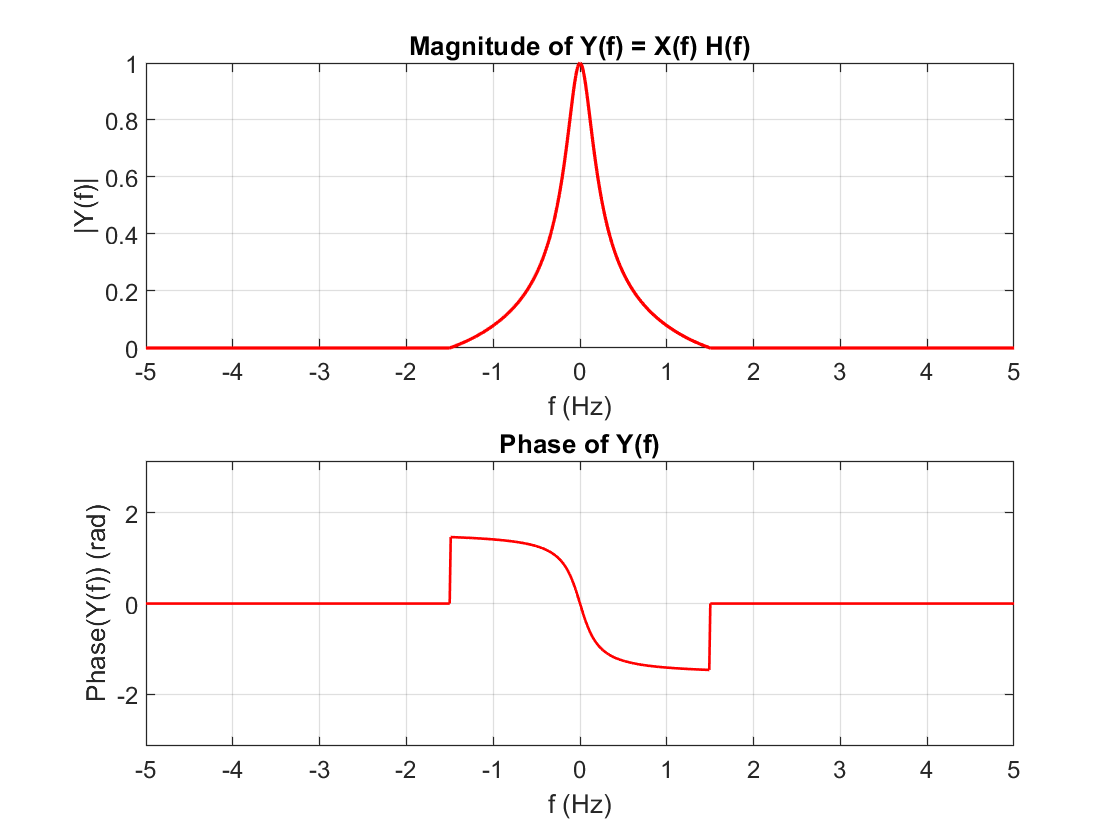

% H(f)
Hf = zeros(size(f));
% support |f| <= 1.5
mask = abs(f) <= 1.5;
Hf(mask) = cos( pi * f(mask) / 3 );  % positive for |f|<1.5, zero at edges

% output spectrum Y(f) = X(f) * H(f)
Yf = Xf .* Hf;
magY = abs(Yf);
phY  = angle(Yf);

% Plots: output magnitude & phase 
figure('Name','Output Spectrum','NumberTitle','off','Position',[700 100 560 420]);
subplot(2,1,1);
plot(f, magY, 'r','LineWidth',1.2);
xlim([-5 5]); xlabel('f (Hz)'); ylabel('|Y(f)|'); grid on;
title('Magnitude of Y(f) = X(f) H(f)');

subplot(2,1,2);
plot(f, phY, 'r','LineWidth',1.0);
xlim([-5 5]); ylim([-pi pi]); xlabel('f (Hz)'); ylabel('Phase(Y(f)) (rad)'); grid on;
title('Phase of Y(f)');

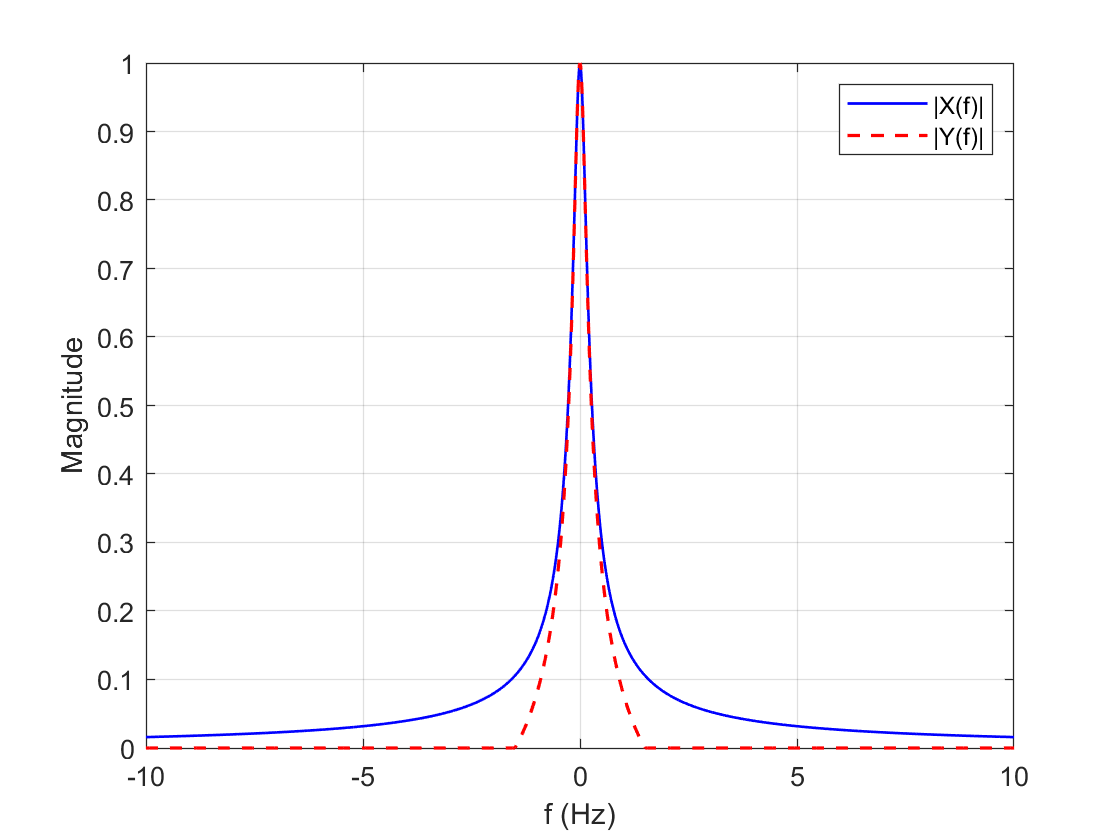

% Compare magnitude of X and Y over a wider range
figure('Name','Mag comparison','NumberTitle','off');
plot(f, magX, 'b', 'LineWidth',1); hold on;
plot(f, magY, 'r--', 'LineWidth',1.2);
xlabel('f (Hz)'); ylabel('Magnitude'); legend('|X(f)|','|Y(f)|'); grid on;
xlim([-10 10]);

We approximate inverse continuous FT:


$$y(t) = \int_{-Fmax}^{Fmax} Y(f) e^{j 2 pi f t} df  \approx  sum_k Y(f_k) e^{j2pi f_k t} * df
$$


We evaluate this at a time grid t_eval

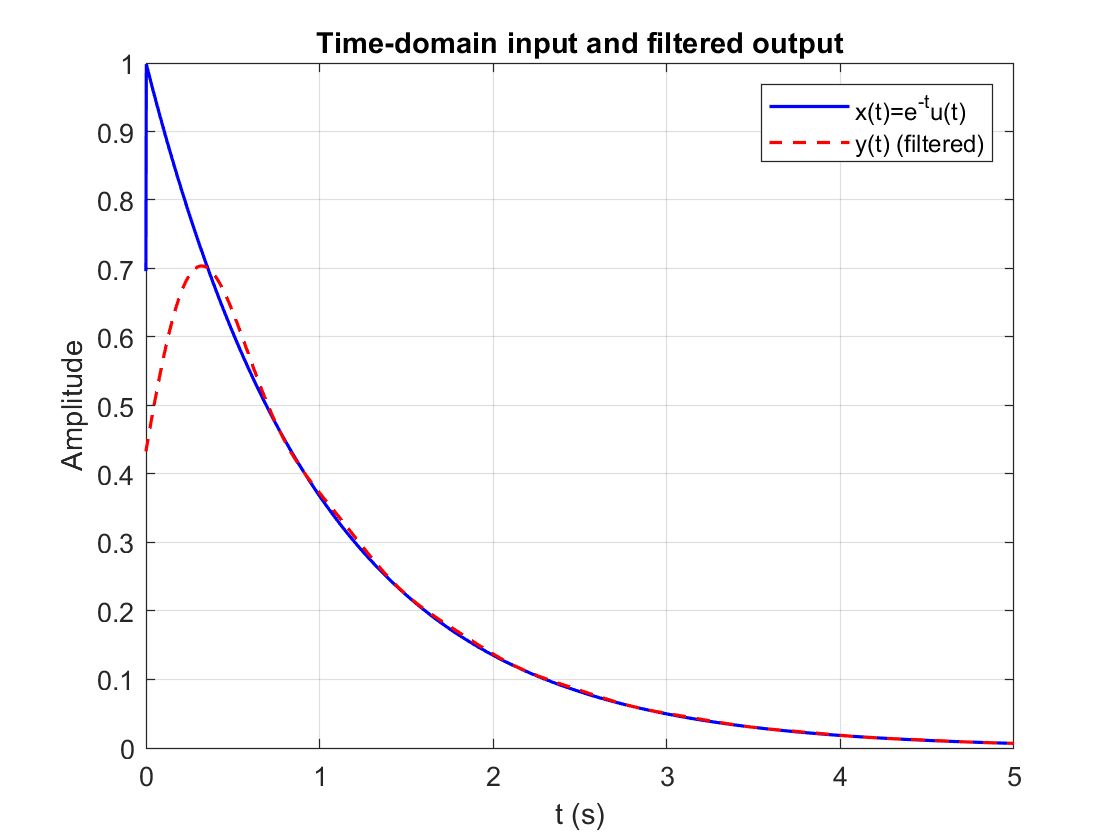


t_eval = linspace(-0.2, 6, 2000);   % choose time window that captures response

% We'll compute in one vectorized operation (should fit for these sizes).
E = exp(1j*2*pi*(f.') * t_eval);   % N x Nt matrix  (8192 x 2000) -> ~131 million entries -> heavy
% To reduce memory, compute in blocks:
Nt = length(t_eval);
y_t = zeros(1, Nt);
blockSize = 256;   % tune if memory issues: smaller -> less mem, more time
K = ceil(Nt/blockSize);

for k = 1:K
    idx_t = (k-1)*blockSize + 1 : min(k*blockSize, Nt);
    % create small exponent matrix for this block
    Eblk = exp(1j*2*pi*(f.') * t_eval(idx_t));   % N x block
    yblk = (Yf * Eblk) * df;   % (1 x N) * (N x block) -> 1 x block
    y_t(idx_t) = yblk;
end

y_t = real(y_t);   % output should be real (numerical small imag may appear)

t_plot = linspace(-0.2, 6, 800);
x_plot = zeros(size(t_plot));
x_plot(t_plot>=0) = exp(-t_plot(t_plot>=0));
figure('Name','Input vs Output (time)','NumberTitle','off');
plot(t_plot, x_plot, 'b', 'LineWidth',1.2); hold on;
plot(t_eval, y_t, 'r--', 'LineWidth',1.2);
legend('x(t)=e^{-t}u(t)','y(t) (filtered)');
xlabel('t (s)'); ylabel('Amplitude'); grid on;
title('Time-domain input and filtered output');
xlim([0 5]);